% MTRN4030: Assignment One in Week 1 :)


## **Question 1**

 Find the stationary points and inflection points of f (x) = cos(x) . Limit your answer to −2π ≤ x ≤ 2π in steps of 0.3 .

disp("Question 1");

Question 1


syms x;
% Define function
f = cos(x);
% Differentiate 1st and 2nd
df = diff(f,x);
dff = diff(df,x);
% Create Step
x_value = -2*pi:0.3:2*pi;
% Sub in and convert from symbol to double
y = subs(df,x,x_value);
y_inf = subs(dff,x,x_value);
y = double(y)

y =          0   -0.2955   -0.5646   -0.7833   -0.9320   -0.9975   -0.9738   -0.8632   -0.6755   -0.4274   -0.1411    0.1577    0.4425    0.6878    0.8716    0.9775    0.9962    0.9258    0.7728    0.5507    0.2794   -0.0168   -0.3115   -0.5784   -0.7937   -0.9380   -0.9985   -0.9699   -0.8546   -0.6630   -0.4121   -0.1245    0.1743    0.4575    0.6999    0.8797    0.9809    0.9946    0.9193    0.7620    0.5366    0.2632


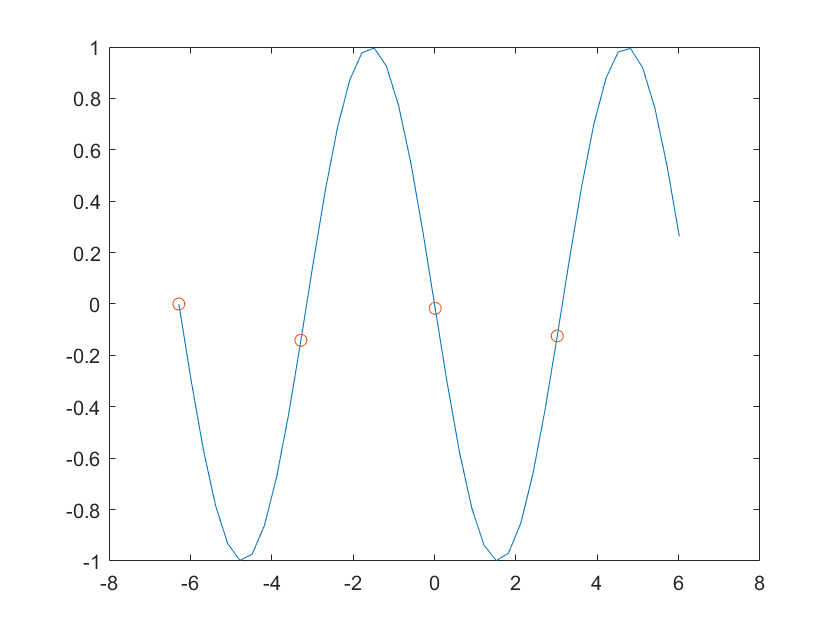

y_inf = double(y_inf);
% Plot
plot(x_value,y);
hold on
% Finds point really close to 0;
offset = find(abs(y)<0.15);
% Plot the points using scatter plot function.
scatter(x_value(offset),y(offset))
hold off

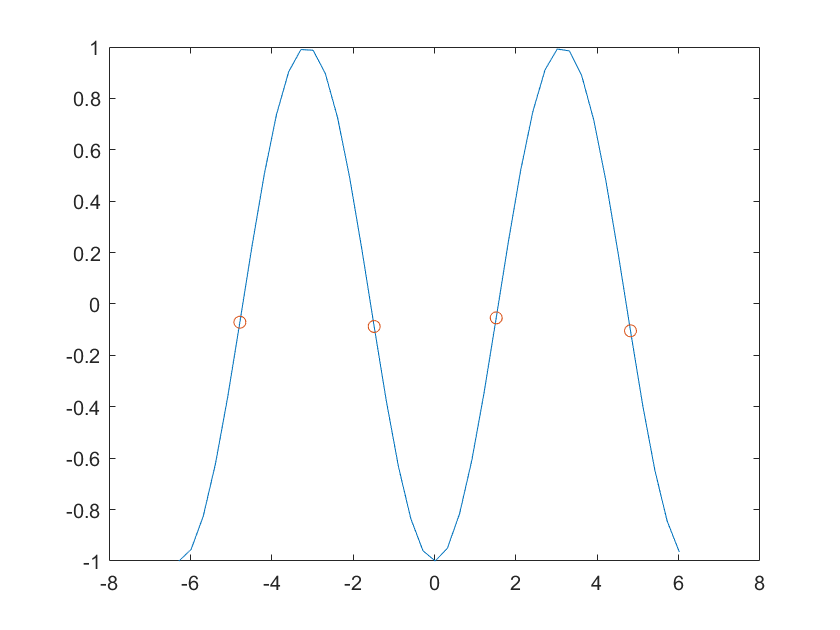

plot(x_value,y_inf);
hold on;
offset = find(abs(y_inf)<0.15);
scatter(x_value(offset),y_inf(offset));
hold off;

## **Question 2**

Find the stationary points and inflection points of f(x ) exp( ) 2 f x = −x , for −2 ≤ x ≤ 2 in steps of 0.2 .

clc; clear;
disp("Question 2")

Question 2


syms x;
f = exp(-x.^2);
df = diff(f,x)

$$df = -2\,x\,{\mathrm{e}}^{-x^{2}}$$

dff = diff(df,x)

$$dff = 4\,x^{2}\,{\mathrm{e}}^{-x^{2}}-2\,{\mathrm{e}}^{-x^{2}}$$

x_value = -2:0.2:2;
y = subs(df,x,x_value);
y = double(y);
y_inf = subs(dff,x,x_value);
y_inf = double(y_inf)

y_inf =     0.2564    0.4292    0.6370    0.8226    0.8908    0.7358    0.2953   -0.3907   -1.1589   -1.7679   -2.0000   -1.7679   -1.1589   -0.3907    0.2953    0.7358    0.8908    0.8226    0.6370    0.4292    0.2564


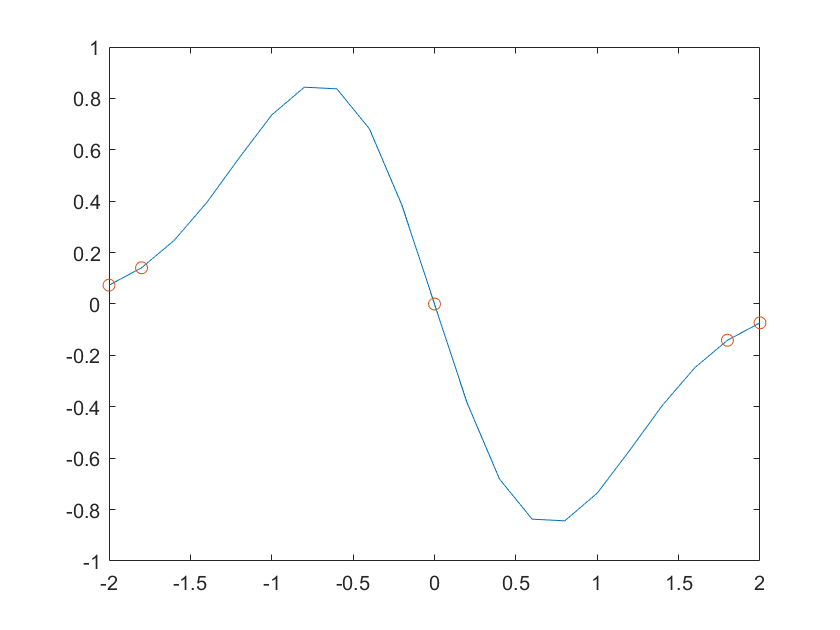

plot(x_value,y)
hold on;
offset = find(abs(y)<0.15);
scatter(x_value(offset),y(offset))
hold off;

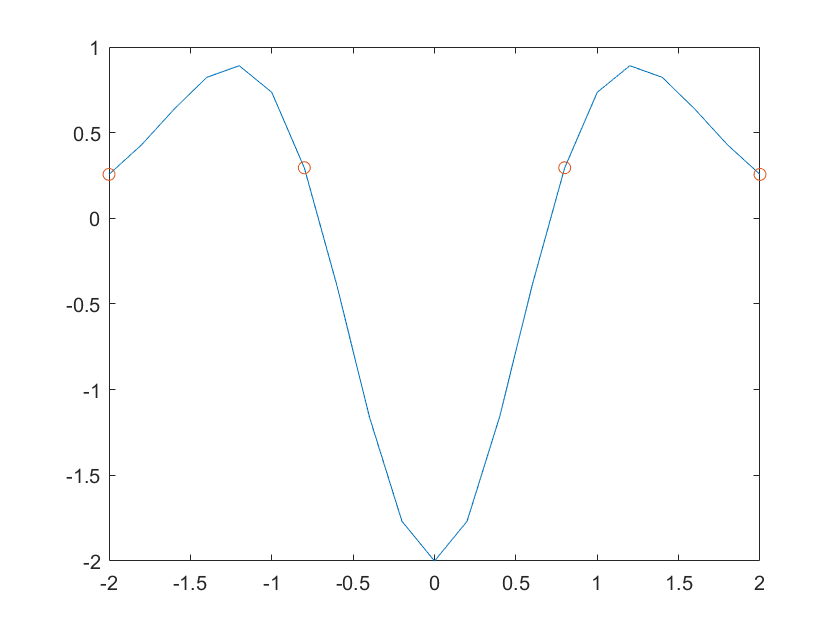

plot(x_value,y_inf);
hold on;
offset = find(abs(y_inf)<0.3);
scatter(x_value(offset),y_inf(offset))
hold off;

## Question 3

Find the global maximum of x x f x c x sin( ) ( ) = sin ( ) = , for −2π ≤ x ≤ 2π in steps of 0.3 . 

clc;clear
disp("Question 3")

Question 3


syms x;
f = sin(x)/x;
df = diff(f,x);
dff = diff(df,x);
x_value = -2*pi:0.3:2*pi;
points = subs(f,x,x_value);
points = double(points);
y = subs(f,x,x_value);
y = double(y)

y =          0   -0.0494   -0.0994   -0.1455   -0.1834   -0.2085   -0.2172   -0.2064   -0.1739   -0.1193   -0.0430    0.0529    0.1649    0.2886    0.4184    0.5482    0.6716    0.7825    0.8750    0.9443    0.9867    1.0000    0.9834    0.9378    0.8657    0.7709    0.6583    0.5338    0.4037    0.2743    0.1517    0.0413   -0.0526   -0.1265   -0.1787   -0.2086   -0.2172   -0.2065   -0.1797   -0.1407   -0.0939   -0.0437


y_inf = subs(df,x,x_value);
y_inf = double(y_inf)

y_inf =    -0.1592   -0.1679   -0.1627   -0.1425   -0.1074   -0.0584    0.0022    0.0714    0.1451    0.2190    0.2884    0.3487    0.3957    0.4257    0.4362    0.4256    0.3938    0.3419    0.2721    0.1879    0.0936   -0.0056   -0.1045   -0.1979   -0.2807   -0.3486   -0.3984   -0.4279   -0.4360   -0.4233   -0.3912   -0.3426   -0.2810   -0.2109   -0.1367   -0.0633    0.0051    0.0645    0.1120    0.1455    0.1640    0.1676


% find stationary point
offset = find(abs(y_inf)<0.3);
y_station = y(offset)

y_station =          0   -0.0494   -0.0994   -0.1455   -0.1834   -0.2085   -0.2172   -0.2064   -0.1739   -0.1193   -0.0430    0.8750    0.9443    0.9867    1.0000    0.9834    0.9378    0.8657   -0.0526   -0.1265   -0.1787   -0.2086   -0.2172   -0.2065   -0.1797   -0.1407   -0.0939   -0.0437


% find 2nd diff points that are less than 0
max_points = find(y_inf(offset) < 0)

max_points =      1     2     3     4     5     6    15    16    17    18    19    20    21    22


new_y = y(max_points)

new_y =          0   -0.0494   -0.0994   -0.1455   -0.1834   -0.2085    0.4184    0.5482    0.6716    0.7825    0.8750    0.9443    0.9867    1.0000


global_y_max = max(new_y)

global_y_max = 1.0000

index = find(y == global_y_max)

index = 22

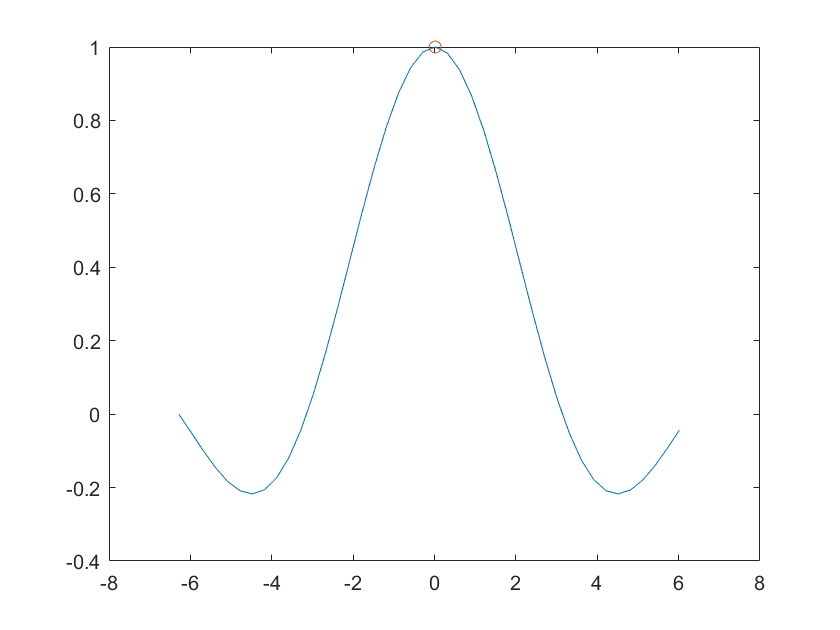

x_max = x_value(index);
plot(x_value,points)
hold on
scatter(x_max,global_y_max);
hold off

## Question 4

clc; clear
disp("Question 4")

Question 4


syms x k;
f = x.^2+k*cos(x)^2

$$f = x^{2}+k\,{\cos\left(x\right)}^{2}$$

df = diff(f,x)

$$df = 2\,x-2\,k\,\cos\left(x\right)\,\sin\left(x\right)$$

dff = diff(df,x)

$$dff = -2\,k\,{\cos\left(x\right)}^{2}+2\,k\,{\sin\left(x\right)}^{2}+2$$

k_val = double(1:1:5)

k_val =      1     2     3     4     5


for i=1:5
    x_value = -2:0.2:2;
    currF = subs(f,k,i);
    currDF = subs(df,k,i);
    currDFF = subs(dff,k,i);
    y = subs(currF,x,x_value);
    y = double(y);
    y_diff = subs(currDF,x,x_value);
    y_diff = double(y_diff)
    y_inf = subs(currDFF,x,x_value);
    y_inf = double(y_inf)
    mini = find(y_inf<0)
    plot(x_value,y)
    hold on;
end

y_diff =    -4.7568   -4.0425   -3.2584   -2.4650   -1.7245   -1.0907   -0.6004   -0.2680   -0.0826   -0.0106         0    0.0106    0.0826    0.2680    0.6004    1.0907    1.7245    2.4650    3.2584    4.0425    4.7568


y_inf =     3.3073    3.7935    3.9966    3.8844    3.4748    2.8323    2.0584    1.2753    0.6066    0.1579         0    0.1579    0.6066    1.2753    2.0584    2.8323    3.4748    3.8844    3.9966    3.7935    3.3073



mini =

  1×0 empty double row vector



y_diff =    -5.5136   -4.4850   -3.3167   -2.1300   -1.0491   -0.1814    0.3991    0.6641    0.6347    0.3788         0   -0.3788   -0.6347   -0.6641   -0.3991    0.1814    1.0491    2.1300    3.3167    4.4850    5.5136


y_inf =     4.6146    5.5870    5.9932    5.7689    4.9496    3.6646    2.1168    0.5506   -0.7868   -1.6842   -2.0000   -1.6842   -0.7868    0.5506    2.1168    3.6646    4.9496    5.7689    5.9932    5.5870    4.6146


mini =      9    10    11    12    13


y_diff =    -6.2704   -4.9276   -3.3751   -1.7950   -0.3736    0.7279    1.3987    1.5961    1.3521    0.7683         0   -0.7683   -1.3521   -1.5961   -1.3987   -0.7279    0.3736    1.7950    3.3751    4.9276    6.2704


y_inf =     5.9219    7.3806    7.9898    7.6533    6.4244    4.4969    2.1752   -0.1741   -2.1802   -3.5264   -4.0000   -3.5264   -2.1802   -0.1741    2.1752    4.4969    6.4244    7.6533    7.9898    7.3806    5.9219


mini =      8     9    10    11    12    13    14


y_diff =    -7.0272   -5.3701   -3.4335   -1.4600    0.3019    1.6372    2.3983    2.5282    2.0694    1.1577         0   -1.1577   -2.0694   -2.5282   -2.3983   -1.6372   -0.3019    1.4600    3.4335    5.3701    7.0272


y_inf =     7.2291    9.1741    9.9864    9.5378    7.8991    5.3292    2.2336   -0.8989   -3.5737   -5.3685   -6.0000   -5.3685   -3.5737   -0.8989    2.2336    5.3292    7.8991    9.5378    9.9864    9.1741    7.2291


mini =      8     9    10    11    12    13    14


y_diff =    -7.7840   -5.8126   -3.4919   -1.1251    0.9773    2.5465    3.3979    3.4602    2.7868    1.5471         0   -1.5471   -2.7868   -3.4602   -3.3979   -2.5465   -0.9773    1.1251    3.4919    5.8126    7.7840


y_inf =     8.5364   10.9676   11.9829   11.4222    9.3739    6.1615    2.2920   -1.6236   -4.9671   -7.2106   -8.0000   -7.2106   -4.9671   -1.6236    2.2920    6.1615    9.3739   11.4222   11.9829   10.9676    8.5364


mini =      8     9    10    11    12    13    14


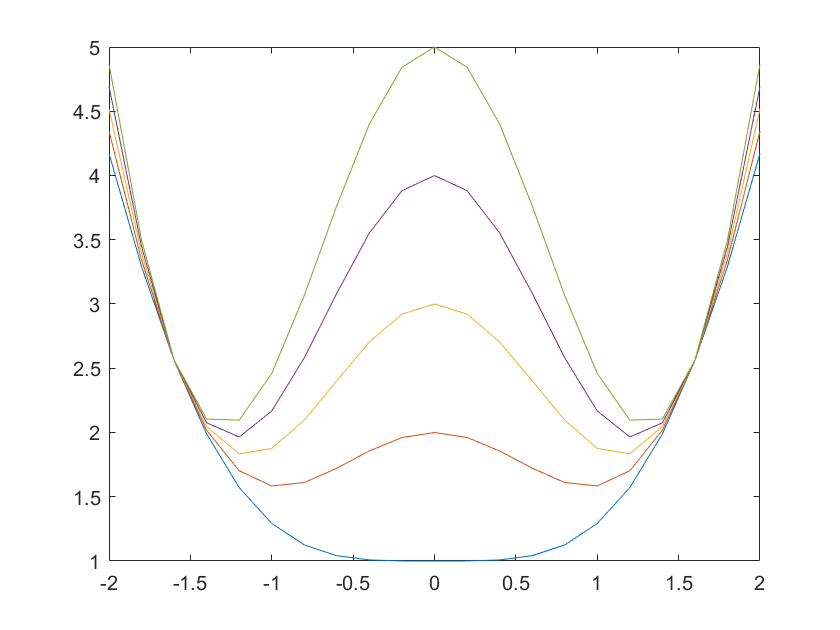


hold off;

## Question 5

## Question 6

## Question 7

A = [2,3;3,5];
B = [-2,2;2,3];
C = [-5,2;2,-2];
Minor_A = [det(A(1)), det(A)]

Minor_A =     2.0000    1.0000


Minor_B = [det(B(1)), det(B)]

Minor_B =     -2   -10


Minor_C = [det(C(1)), det(C)]

Minor_C =     -5     6
